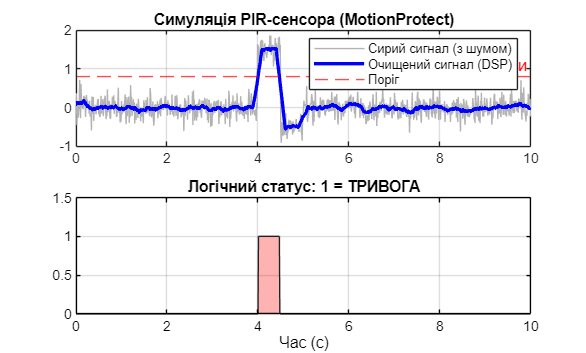

clc; clear; close all;

% --- 1. Генерація "Сирого" сигналу з датчика ---
fs = 100;              % Частота дискретизації (100 вимірів на секунду)
T = 10;                % Час симуляції (10 секунд)
t = 0:1/fs:T-1/fs;     % Часовий вектор
N = length(t);

% Створюємо просто шум (сенсор у спокої)
noise = 0.2 * randn(1, N); 

% Додаємо "Людину" (подія на 4-й секунді)
human_signal = zeros(1, N);
human_signal(400:450) = 1.5; % Сплеск напруги (людина пройшла)
human_signal(451:500) = -0.5; % Віддача

% Підсумковий сигнал, який бачить процесор
raw_signal = human_signal + noise;

% --- 2. Цифрова обробка (DSP) ---
% Простий фільтр "Ковзне середнє" (Moving Average)
window_size = 20; % Усереднюємо по 20 точках
filtered_signal = movmean(raw_signal, window_size);

% Поріг спрацювання (Threshold)
alarm_threshold = 0.8; 

% --- 3. Логіка тривоги ---
alarm_triggered = filtered_signal > alarm_threshold;

% --- 4. Візуалізація для інженера ---
figure('Color', 'w');
subplot(2,1,1);
plot(t, raw_signal, 'Color', [0.7 0.7 0.7]); hold on;
plot(t, filtered_signal, 'b', 'LineWidth', 2);
yline(alarm_threshold, 'r--', 'Поріг тривоги');
legend('Сирий сигнал (з шумом)', 'Очищений сигнал (DSP)', 'Поріг');
title('Симуляція PIR-сенсора (MotionProtect)');
grid on;

subplot(2,1,2);
area(t, alarm_triggered, 'FaceColor', 'r', 'FaceAlpha', 0.3);
ylim([0 1.5]);
title('Логічний статус: 1 = ТРИВОГА');
xlabel('Час (с)');
grid on;